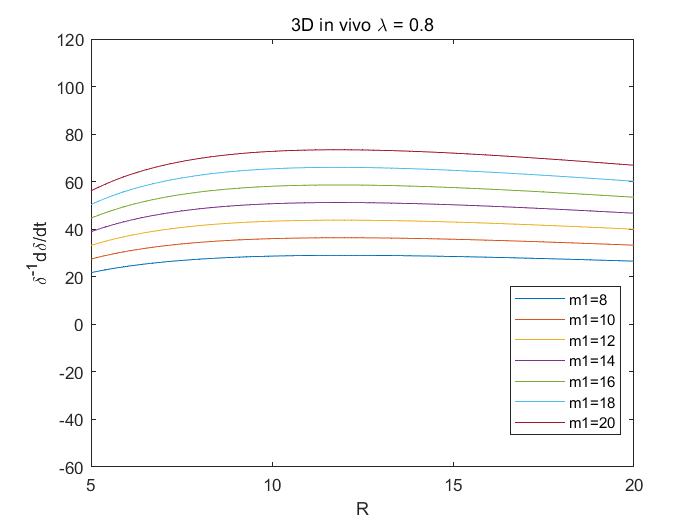

clc;clear;close;

% effect of l on evol function is more powerful than m
G=1;
C_b=10;
%l = 3; % smaller threshold
l = 20; %find threshold in 0.4-0.45 
%l=200; %find threshold in 0.6-0.65 %cannot draw lambda=100 too big
m1=[8 10 12 14 16 18 20];
R = 0:0.1:50;
%R = 5:0.1:20;

xmin = 5; % X轴的最小值
xmax = 20; % X轴的最大值
%xlim([xmin xmax])
ymin = -60; % X轴的最小值
ymax = 120; % X轴的最大值
%ylim([ymin ymax])


%lambda = 0.8;

lambda=0.8;

for i=1:length(m1)
    sigma2= v_3D(l,R,m1(i),lambda,C_b,G);
    plot(R, sigma2)
    axis([xmin xmax ymin ymax])
    hold on
end
title('3D in vivo \lambda = 0.8')
legend('m1=8','m1=10','m1=12','m1=14','m1=16','m1=18','m1=20')
legend('location','best')
xlabel('R')
ylabel('\delta^{-1}d\delta/dt')
%plot(R,sigma);
hold off;

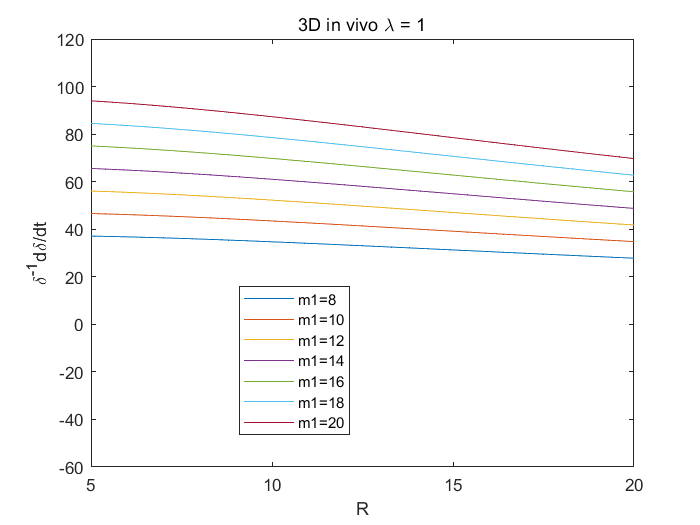


% lambda = 1;

lambda=1;
G=1;
C_b=10;

for i=1:length(m1)
    sigma2= v_3D(l,R,m1(i),lambda,C_b,G);
    plot(R, sigma2)
    axis([xmin xmax ymin ymax])
    hold on
end
title('3D in vivo \lambda = 1')
legend('m1=8','m1=10','m1=12','m1=14','m1=16','m1=18','m1=20')
legend('location','best')
xlabel('R')
ylabel('\delta^{-1}d\delta/dt')
%plot(R,sigma);
hold off;

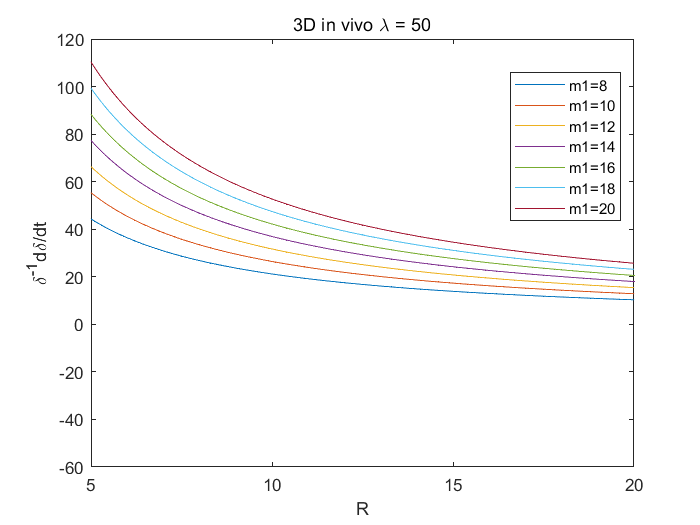


% lambda = 50;

lambda=50;
G=1;
C_b=10;

for i=1:length(m1)
    sigma2= v_3D(l,R,m1(i),lambda,C_b,G);
    plot(R, sigma2)
    axis([xmin xmax ymin ymax])
    hold on
end
title('3D in vivo \lambda = 50')
legend('m1=8','m1=10','m1=12','m1=14','m1=16','m1=18','m1=20')
legend('location','best')
xlabel('R')
ylabel('\delta^{-1}d\delta/dt')
%plot(R,sigma);
hold off;

function sigma= v_3D(l,R,m,lambda,C_b,G)
    sigma_A = (G.*C_b.*((( (l+m.*l+1).*((3.*R+2).*lambda.^(3/2)+sqrt(lambda).*(R-2) ).*R.*besselk(l+1/2, R) +2.* besselk(l-1/2, R).*(R+1).*(R.*(R-m.*l./2-1).*lambda.^(3/2)-(m.*l+2).*(R-2).*sqrt(lambda)./2 + m.*l.*lambda.*(-2+(lambda+1).*R)./2)) .*cosh(sqrt(lambda).*R).^3 + sinh(sqrt(lambda).*R).* ((l+m*l+1).*((lambda.^2+3.*lambda).*R+lambda.^2-1).*R .*besselk(l+1/2, R)+besselk(l-1/2, R).*(R+1).*((2.*R.*m.*l-m.*l).*lambda.^(3/2)-m.*l.*sqrt(lambda)+(lambda.^2+lambda).*R.^2-2*lambda.*(m.*l+2).*R+(lambda+1).*(m.*l+2))).*cosh(sqrt(lambda).*R).^2+(-((2.*R+2).*lambda.^(3/2)+sqrt(lambda).*(R-2)).*(l+m.*l+1).*R.* besselk(l+1/2, R) -2.*(lambda.^(3/2).*R.^2+(R-2).*((-m*l-2).*sqrt(lambda)+m*l*lambda)./2 ).* besselk(l-1/2, R).*(R+1)).*cosh(sqrt(lambda).*R)-sinh(sqrt(lambda).*R).*(R.*(l+m*l+1).*(lambda.*R+lambda-1).*besselk(l+1/2, R)+besselk(l-1/2, R).*(R+1).*(R.^2.*lambda-m*l*sqrt(lambda)+m*l+2))).*besseli(l+1/2, sqrt(lambda).*R)+besselk(l+1/2, R).*((m*l.*(R+1).*(R-2).*lambda.^(3/2)+R.*m*l.*(R+1).*lambda.^(5/2)-lambda.*(-2+(lambda+1).*R).*(R.^2+ (m*l+2).*R+m*l+2)).*cosh(sqrt(lambda).*R).^3-2.*((R-1/2).*(R.^2+(m*l+2).*R+m*l+2).*lambda.^(3/2)+(-R.^2/2+(-m*l/2-1).*R-m*l/2-1).*sqrt(lambda)-m*l.*(R+1).*lambda.*(lambda.*R-lambda./2-1/2)).*sinh(sqrt(lambda).*R).*cosh(sqrt(lambda).*R).^2+(-m.*l.*(R+1).*lambda.^(3/2)+lambda.*(R.^2+(m.*l+2).*R+m*l+2)).*(R-2).*cosh(sqrt(lambda).*R)-sinh(sqrt(lambda).*R).*((R.^2+(m*l+2).*R+m*l+2).*sqrt(lambda)-m*l.*(R+1).*lambda)).*besseli(l-1/2,sqrt(lambda).*R)));
    sigma_B =( sqrt(lambda).*( sqrt(lambda).*cosh(sqrt(lambda).*R)+sinh(sqrt(lambda).*R) ).*( besselk(l-1/2, R).*( sqrt(lambda).*cosh(sqrt(lambda).*R) +sinh(sqrt(lambda).*R)).*besseli(l+1/2,sqrt(lambda).*R)+besselk(l+1/2, R).*besseli(l-1/2,sqrt(lambda).*R).*( cosh(sqrt(lambda).*R).*lambda+sinh(sqrt(lambda).*R).*sqrt(lambda) )).*(cosh(sqrt(lambda).*R)*lambda+sinh(sqrt(lambda).*R).*sqrt(lambda)).*R.^3);
    sigma = sigma_A ./ sigma_B;
end